Q1) Create a 3-by-1 column vector and 3x3 matrix with all elements as random numbers  between 0 and 10. Take the product of the matrix and column vector and calculate the  average of the resulting vector. Do this 1000 times and get the average of the average.  What is this average?

running_sum = 0

running_sum = 0

%comment 
for c = 1:1000
    m_1 = rand(3, 1) .* 10;
    m_2 = rand(3, 3) .* 10;
    result = mean(m_2 * m_1);
    running_sum = running_sum + result;
end
disp(running_sum/1000);

   74.8262



Q2) Create a 5x5 matrix with all zeros on the first row and column and values starting from  1 to 16 starting from element M(2,2) to element M(5,5) as shown below using a nested  for loop: 𝑀 = [0 0 0 0 0; 0 1 2 3 4; 0 5 6 7 8; 0 9 10 11 12; 0 13 14 15 16 ] 

m_3 = zeros(5)

m_3 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


counter = 1;
for c = 2:5
    for k = 2:5
        m_3(c, k) = counter;
        counter = counter + 1;
    end
end
disp(m_3);

     0     0     0     0     0
     0     1     2     3     4
     0     5     6     7     8
     0     9    10    11    12
     0    13    14    15    16



Q3) Find the determinant of the matrix shown in question 2. 

c_1 = det(m_3)

c_1 = 0

Q4) Create a 5x5 identity matrix (I) and multiply it by the matrix (M) in question 2.

m_4 = eye(5)

m_4 =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


m_5 = m_3 * m_4

m_5 =      0     0     0     0     0
     0     1     2     3     4
     0     5     6     7     8
     0     9    10    11    12
     0    13    14    15    16


     0     0     0     0     0
     0     1     2     3     4
     0     5     6     7     8
     0     9    10    11    12
     0    13    14    15    16



disp(m_5) % should get m_3 back

Q5) Find the sum of the fifth row of matrix M in question 2

c_2 = sum(m_3(5,:))

c_2 = 58

Q6) Create a vector V that contains only the last column of matrix M (with matrix operations, avoid direct assignment).

V = m_3(:,5)

V =      0
     4
     8
    12
    16


Q7) Multiply matrix M by the vector V found in question 6.

m_6 = m_3 * V

m_6 =      0
   120
   280
   440
   600


Q8) Generate a plot for 𝑦1 = 0.1𝑒^(2𝑡) and 𝑦2 = 10^(𝑡^2) where t is the time vector that ranges from 0 to 5 seconds with timesteps of 0.01 seconds. Mark the plots with colors of your own choice and set the plot title as “Question 9.”

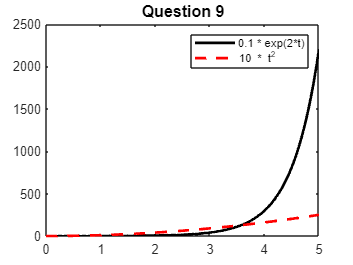

timestep = 0.01;
t = 0:timestep:5; % x-axis time vector
y_1 = 0.1 * exp(2*t);
y_2 = 10 * t.^2;

plot(t, y_1, 'black-', t, y_2, 'r--', 'linewidth', 2)
xlabel('')
ylabel('')
title('Question 9', 'FontSize',12)
legend('0.1 * exp(2*t)', '10 * t^2')

Q9) From Question 8, plot the same figures in different line styles (instead of dots, use circles, plus any other style of your preference) and different colors, also change the thickness of the data point marker.

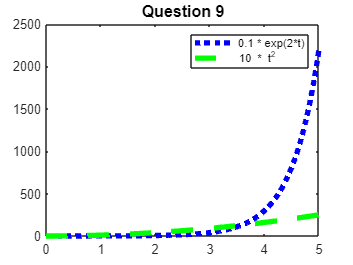

timestep = 0.01;
t = 0:timestep:5; % x-axis time vector
y_1 = 0.1 * exp(2*t);
y_2 = 10 * t.^2;

plot(t, y_1, 'blue:', t, y_2, 'green--', 'linewidth', 4)
xlabel('')
ylabel('')
title('Question 9', 'FontSize',12)
legend('0.1 * exp(2*t)', '10 * t^2')

Q10) Write a function that takes as an input the radius and center location (x,y) of a circle and provides as an output the perimeter, area, and plot of the circle.

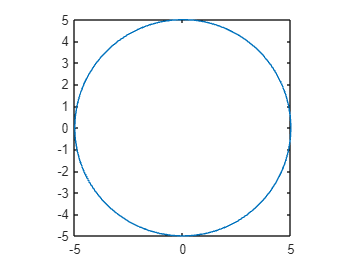

area = 78.5398

perimeter = 31.4159

circle_plot =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [5 4.9726 4.8907 4.7553 4.5677 4.3301 4.0451 3.7157 3.3457 2.9389 2.5000 2.0337 1.5451 1.0396 0.5226 3.0616e-16 -0.5226 -1.0396 -1.5451 -2.0337 -2.5000 -2.9389 -3.3457 -3.7157 -4.0451 -4.3301 -4.5677 -4.7553 -4.8907 -4.9726 -5 … ]
              YData: [0 0.5226 1.0396 1.5451 2.0337 2.5000 2.9389 3.3457 3.7157 4.0451 4.3301 4.5677 4.7553 4.8907 4.9726 5 4.9726 4.8907 4.7553 4.5677 4.3301 4.0451 3.7157 3.3457 2.9389 2.5000 2.0337 1.5451 1.0396 0.5226 6.1232e-16 -0.5226 -1.0396 … ]

  Show 

[area, perimeter, circle_plot] = get_circle(5, 0, 0)

Q11) Write a MATLAB code that prompts the user to enter a 3x3 matrix or any square matrix. Raise every element in that matrix to the power of 2, calculate that determinant, and show a notification whether the determinant is positive or negative. Your code should also display an error message if the entered data is not a 3x3 matrix or not a square matrix. In the end, your code should output the squared matrix and the value of the determinant.

prompt = "Enter a 3x3 matrix: ";
m_7 = input(prompt)

m_7 =      8     1     6
     3     5     7
     4     9     2


count_rows = height(m_7); % Computes number of rows in m_7
count_columns = width(m_7); % Computes number of columns in m_7

if count_rows ~= 3
    error("The matrix does not have 3 rows")
end

if count_columns ~= 3
    error("The matrix does not have 3 columns")
end

c_3 = det(m_7)

c_3 = -360

if c_3 < 0
    fprintf("The matrix has a negative determinant")

else
    fprintf("The matrix has a positive determinant")

end

The matrix has a negative determinant

disp(m_7)

     8     1     6
     3     5     7
     4     9     2



disp(c_3)

  -360



Q12) Create a function that prompts a user to enter their weight and height (in pounds and inches respectively) to calculate the BMI (703 ∗ 𝑤𝑒𝑖𝑔ℎ𝑡/[ℎ𝑒𝑖𝑔ℎ𝑡]2 ). Display what category the person belongs to:

𝐵𝑀𝐼 ≤ 18.5: 𝑢𝑛𝑑𝑒𝑟𝑤𝑒𝑖𝑔ℎ𝑡. 18.5 < 𝐵𝑀𝐼 ≤ 24.9: 𝑁𝑜𝑟𝑚𝑎𝑙. 24.9 < 𝐵𝑀𝐼 ≤ 29.9: 𝑂𝑣𝑒𝑟𝑤𝑒𝑖𝑔ℎ𝑡. 𝐵𝑀𝐼 > 29.9: 𝑂𝑏𝑒𝑠𝑒

get_bmi()

Your BMI is 1.544864e+01
You are underweight

Q13) Write a code that generates the plot below (Modifications on the figure should be done by code, not through the GUI):

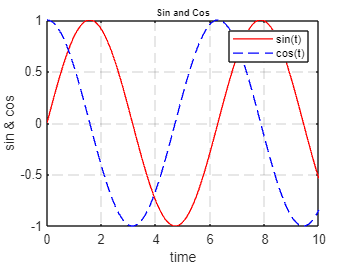

n = pi/100;
t = 0:n:10;

y_1 = sin(t);
y_2 = cos(t);

plot(t, y_1, "red-", t, y_2, 'blue--', 'linewidth', 1)
xlabel('time')
ylabel('sin & cos')
title('Sin and Cos', 'FontSize', 7)
grid on
set(gca,'GridLineStyle','--')
legend('sin(t)', 'cos(t)')

Q14) Solve the following system of linear equations using MATLAB functions:

5𝑥 − 3𝑦 + 2𝑧 = 10, −3𝑥 + 8𝑦 + 4𝑧 = 20, 2𝑥 + 4𝑦 − 9𝑧 = 9

m_8 = [5 -3 2; -3 8 4; 2 4 -9]

m_8 =      5    -3     2
    -3     8     4
     2     4    -9


m_9 = [10; 20; 9]

m_9 =     10
    20
     9


m_10 = linsolve(m_8, m_9)

m_10 =     3.4442
    3.1982
    1.1868


function [area, perimeter, circle_plot] = get_circle(radius, x, y)
    % https://www.youtube.com/watch?v=xkbG426Yi-0
    area = pi*radius^2;
    perimeter = 2 * pi * radius;

    th = 0:pi/30:2*pi;
    xunit = radius * cos(th) + x;
    yunit = radius * sin(th) + y;
    circle_plot = plot(xunit, yunit);
    axis square
end

function get_bmi()
    prompt = "Enter your weight in pounds: ";
    weight = input(prompt);
    prompt = "Enter your height in inches: ";
    height = input(prompt);

    user_bmi = 703 * weight / height^2;
    fprintf("Your BMI is %d\n", user_bmi);

    if user_bmi <= 18.6
        fprintf("You are underweight")
    elseif user_bmi > 29.9
        fprintf("You are obese")
    elseif 18.5 < user_bmi && user_bmi <= 24.9
        fprintf("You are normal")
    elseif 24.9 < user_bmi && user_bmi <= 29.9
        fprintf("You are overweight")
    end
end